%{
ES115 Engineering Computer Applications 
Module 1 Project: Two-Sensor Calibration and Agreement Check

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 25, 2026

Purpose:
The purpose of this project is to compare two sensors by building linear calibration
models for each. By calculating their individual curves and analyzing the difference
between their outputs in MATLAB, we can determine how they diverge over an operational
range and identify the exact point where they agree most closely. This process 
demonstrates how engineering tools are used to validate and sync measurement hardware.

Inputs:
- Calibration Points: Two known (x, y) coordinates for each sensor
- Input Range (x): 0 to 30
- Step Size: 1 unit

Outputs:
- Model Parameters: Calculated slope (m) and intercept (b) for both sensors
- Sensor Readings (y_1, y_2): Vectors of output values for the full range
- Error Vector (e): Calculated difference between the two sensors
- Optimal Agreement Point: The (x) value where absolute error is minimized

Engineering Workflows:
- Sensor Calibration: Creating mathematical models from known reference points
- Error Analysis: Quantifying and plotting the divergence between measurement systems
- System Optimization: Finding the "best fit" or intersection point of two competing hardware models

MATLAB Tools:
- Vector Arithmetic: Solving \(mx+b\) across a range of values simultaneously
- min() & abs(): Combining functions to locate the smallest magnitude of error
- plot(): Generating visual comparisons and error profiles
- legend(): Distinguishing between different data sets on a single graph
%}


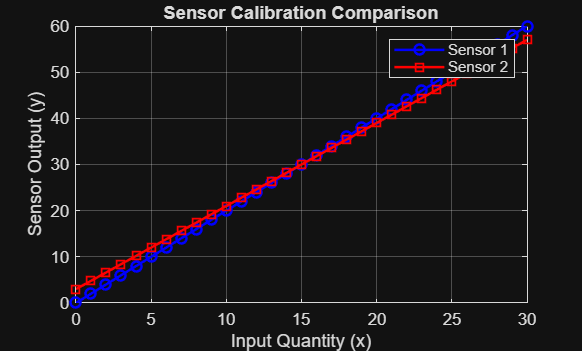

x1a = 5; y1a = 10; x1b = 25; y1b = 50;
m1 = (y1b - y1a) / (x1b - x1a);
b1 = y1a - m1 * x1a;

x2a = 5; y2a = 12; x2b = 25; y2b = 48;
m2 = (y2b - y2a) / (x2b - x2a);
b2 = y2a - m2 * x2a;

x = 0:1:30;
y1 = m1*x + b1;
y2 = m2*x + b2;

figure;
plot(x, y1, 'b-o', x, y2, 'r-s', 'LineWidth', 1.5);
grid on;
xlabel('Input Quantity (x)');
ylabel('Sensor Output (y)');
title('Sensor Calibration Comparison');
legend('Sensor 1', 'Sensor 2');

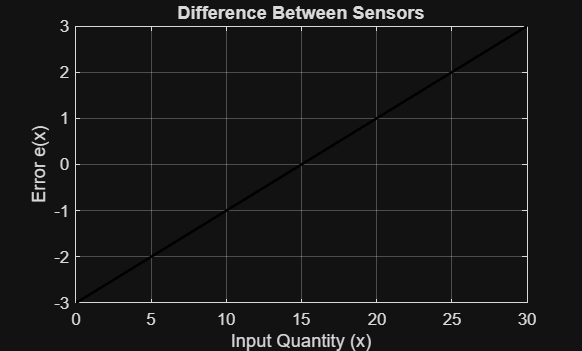


e = y1 - y2;
figure;
plot(x, e, 'k', 'LineWidth', 1.5);
grid on;
xlabel('Input Quantity (x)');
ylabel('Error e(x)');
title('Difference Between Sensors');


[min_err, idx] = min(abs(e));
best_x = x(idx);

fprintf('Sensors agree best at x = %d with an error of %.2f.\n', best_x, min_err);

Sensors agree best at x = 15 with an error of 0.00.
